PMR3523 Controle Moderno

# Entrega 6 - Posicionamento Dinâmico de Navios

Ângelo Bianco Yanagita - 6649978

Diôgo Cavalcante Lopes - 11180872

set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

# Introdução ao Sistema

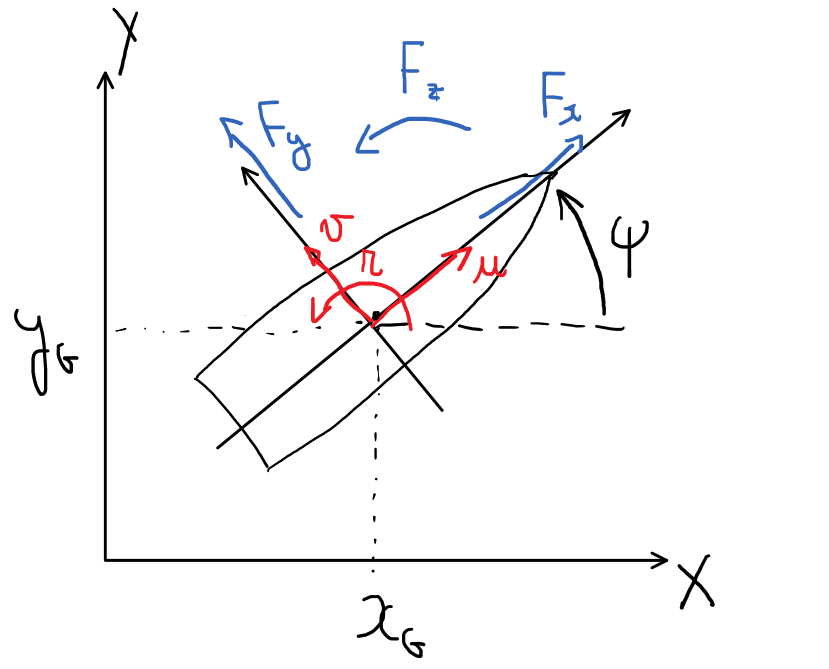

As equações utilizadas são:


$$(1) \; \dot{x}_G=u\cdot cos(\psi)-v\cdot sin(\psi)\\
(2) \; \dot{y}_G=u\cdot sin(\psi)+v\cdot cos(\psi)\\
(3) \; \dot{\psi}=r \\
(4) \; (M+M_{11})\dot{u}-(M+M_{22})v\cdot r -(M\cdot x_G + M_{26})r^2 = F_x \\
(5) \; (M+M_{22})\dot{v}+(M\cdot x_G+M_{26})\dot{r} +(M + M_{11})u\cdot r = F_y \\
(6) \; (I_Z+M_{66})\dot{r}+(M\cdot x_G+M_{26})(\dot{v}+u\cdot r) + (M_{22} - M_{11})u\cdot v = M_z
$$


Sendo as variáveis:

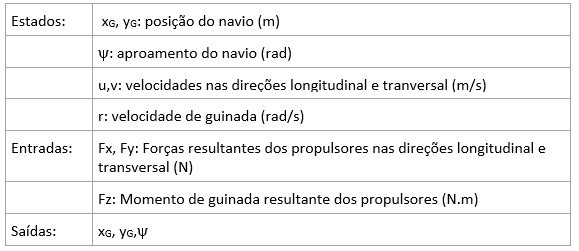


$$\begin{array}{l}
x={\left\lbrack \begin{array}{cccccc}
x_g  & y_g  & \psi \; & u & v & r
\end{array}\right\rbrack }^T \\
u={\left\lbrack \begin{array}{ccc}
F_x  & F_y  & F_z 
\end{array}\right\rbrack }^T \\
y={\left\lbrack \begin{array}{ccc}
x_g  & y_g  & \psi \;
\end{array}\right\rbrack }^T 
\end{array}$$


Considerando os parâmetros do navio de suporte à plataforma Maersk Handler:  

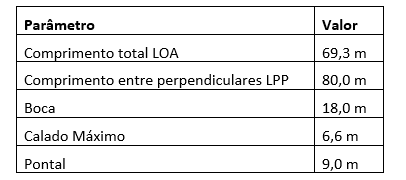


$$M= 7.24\cdot 10^{-3} \; Mton \\
I_Z=2.75 \; Mton.m^2 \\
M_{11}= 6.4\cdot10^{-4} \; Mton \\
M_{22}=6.4\cdot 10^{-3} \; Mton \\
M_{66}=1.56 \; Mton.m^2 \\
M_{26}=7.9\cdot 10^{-3} \; Mton.m^2 \\
x_G=0$$


Saturações nas forças de controle:


$$F_x \le 0.5 \; GN \\
F_y \le 0.5 \; GN \\
M_z \le 0.02 \; GN.m \\$$


%ton
%{
m = 7240;
izz = 2750e3;
m11 = 640;
m22 = 6400;
m66 = 1560e3;
m26 = 7900;
%}

%kton
%{
m = 7.240;
izz = 2750;
m11 = 0.64;
m22 = 6.4;
m66 = 1560;
m26 = 7.9;
%}

%10 Mton ou 10^7 kg
m = 0.7240e-3;
izz = 275e-3;
m11 = 0.0640e-3;
m22 = 0.6400e-3;
m66 = 156e-3;
m26 = 0.7900e-3;

E as condições de linearização:


$$x_G^*=u^*=y_G^*=v^*=\psi^*=r^*=0$$



$$F_x=F_y=M_z=0$$


Utilizando o método de linearização dinâmica com Série de Taylor, obtém-se as seguintes matrizes do espaço de estados:


$$\begin{array}{l}
\delta \dot{x} =A\delta x\left(t\right)+B\delta u\left(t\right)\\
\;\delta y=C\delta x\left(t\right)+D\delta u\left(t\right)\;
\end{array}$$


onde:


$$\delta x= \left[\matrix{\delta x_G\cr
             \delta y_G\cr
             \delta \psi\cr
              \delta u\cr
              \delta v\cr
               \delta r}\right]$$
  
$$\delta \dot{x}= \left[\matrix{\delta u\cr
             \delta v\cr
             \delta r\cr
              \delta \dot{u}\cr
              \delta \dot{v}\cr
               \delta \dot{r}}\right]$$
 
$$\delta u= \left[\matrix{F_x\cr
             F_y\cr
               M_z}\right]$$
 
$$\delta y= \left[\matrix{x_G\cr
             y_G\cr
               \psi}\right]$$



$$A_{6x6}=\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$
 
$$B_{6x3}=10 ^{-10}\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
1269  & 0 & 0\\
0 & 734 & -1,345\\
0 & -1,345 & 2,323
\end{array}\right\rbrack$$
 
$$C_{3x6}=\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack$$
  
$$D=\left[ \begin{array}{c}
0
\end{array}\right]$$


d=(m+m22)*(izz+m66)-m26^2;

A = [0 0 0 1 0 0
     0 0 0 0 1 0
     0 0 0 0 0 1
     0 0 0 0 0 0
     0 0 0 0 0 0
     0 0 0 0 0 0];
 
B = [0 0 0 
    0 0 0
    0 0 0
    1/(m+m11) 0 0
    0 (izz+m66)/d -m26/d
    0 -m26/d (m+m22)/d];

C = [1 0 0 0 0 0
    0 1 0 0 0 0
    0 0 1 0 0 0];

D = 0;

t = 0:0.01:100;
i = 1; % contador para os gráficos

# Matriz de Transferência ($G$)

A partir das matrizes $A$, $B$, $C$ e $D$,  podemos obter a matriz de transferência do sistema MIMI. Para tal, calcula-se:


$$G=\frac{C \cdot Adj(sI-A) \cdot B + D \cdot det(sI-A)}{det(sI-A)}$$


Como $D=[0]$:


$$G=\frac{C \cdot Adj(sI-A) \cdot B}{det(sI-A)}$$


Seguindo com os cálculos, temos que:


$$Adj(sI-A)_{6x6}=\left\lbrack \begin{array}{cccccc}
s^5 & 0 & 0 & s^4 & 0 & 0\\
0 & s^5 & 0 & 0 & s^4 & 0\\
0 & 0 & s^5 & 0 & 0 & s^4\\
0 & 0 & 0 & s^5 & 0 & 0\\
0 & 0 & 0 & 0 & s^5 & 0\\
0 & 0 & 0 & 0 & 0 & s^5
\end{array}\right\rbrack$$
 


$$det(sI-A)=s^6$$


O que resulta em:


$$G=\left[\matrix{1269 \cdot\frac{1}{s^2} & 0 & 0 \cr
0 & 733.9 \cdot\frac{1}{s^2} & -1.345 \cdot\frac{1}{s^2} \cr
0 & -1.345\cdot\frac{1}{s^2} & 2.323\cdot\frac{1}{s^2}}\right]$$


polos_do_sistema = eig(A);

%Matriz adjunta
syms s

sI = [s 0 0 0 0 0
    0 s 0 0 0 0 
    0 0 s 0 0 0
    0 0 0 s 0 0
    0 0 0 0 s 0
    0 0 0 0 0 s];

sI_A = sI-A;
adjunta = adjoint(sI_A);

%Determinante

determinante = det(sI_A);

%Zeros da MF
numerador = C*adjunta*B;
zeros_MF = det(C*adjunta*B);

G = (C*adjunta*B)/determinante;
G_numeric = vpa((C*adjunta*B)/determinante);

# Determinação da Largura de Banda de cada TF

Para determinar a largura de banda, devemos analisar o diagrama de Bode para cada uma das TFs individualmente e obter a frequência de corte: a frequência para qual o gráfico de magnitude têm valor de -3dB.

## Para a primeira TF:


$$G(1,1)=1269 \cdot \frac{1}{s^2}$$


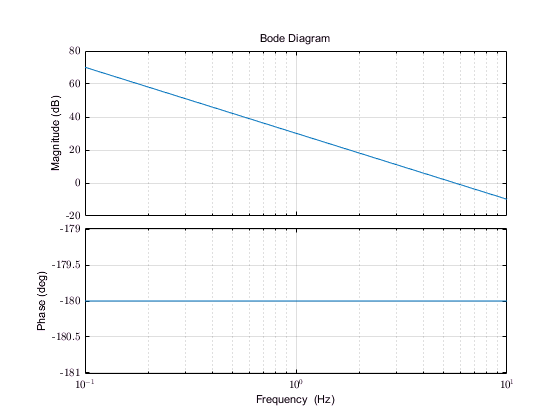

freq=[0 0 0 0];
freq(1)=bode_sys_plot(1,G_numeric);

Onde obtemos uma frequência de corte $f_{c_1}=4.7731\; Hz
$

## Para a segunda TF:


$$G(2,2)=733.9 \cdot \frac{1}{s^2}$$


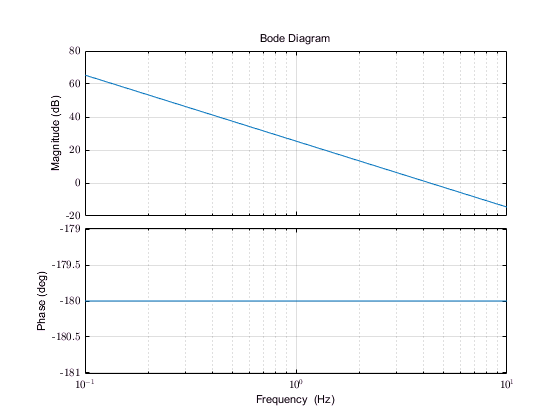

freq(2)=bode_sys_plot(2,G_numeric);

Onde obtemos uma frequência de corte $f_{c_1}=4.6473 \;Hz
$

## Para a terceira TF:


$$G(2,3)=G(3,2) =-1.345 \cdot \frac{1}{s^2}$$


freq =     4.7731    4.6473    0.1989         0


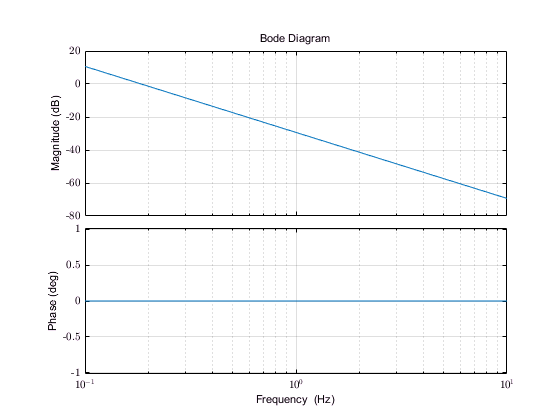

freq(3)=bode_sys_plot(3,G_numeric)

Onde obtemos uma frequência de corte $f_{c_3}=0.1989 Hz
$

## Para a quarta TF:


$$G(3,3)=2.323 \cdot \frac{1}{s^2}$$


freq =     4.7731    4.6473    0.1989    0.2610


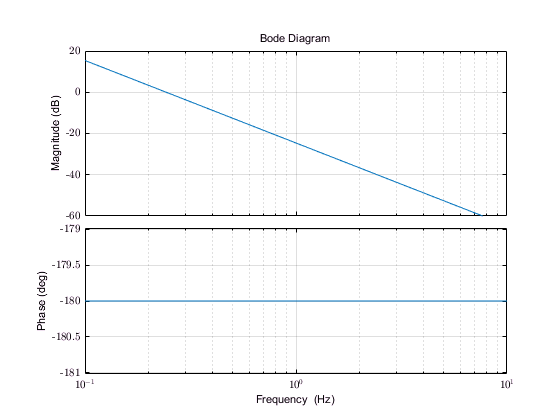

freq(4)=bode_sys_plot(4,G_numeric)

Onde obtemos uma frequência de corte $f_{c_4}=0.261 \;Hz
$

# Determinação do período de amostragem ($T_a$)

De acordo com o teorema de Nyquist, dado um sinal a ser amostrado na frequência de interesse $f$, a frequência de amostragem $f_a$ de modo que não haja perda de informação durante aquisição deve seguir o seguinte critério:


$$f_a > 2\cdot f$$


dado que $T_a= \frac{1}{f_a}$ temos:


$$T_a < \frac{1}{2\cdot f}$$


Como nosso sistema é MIMO, devemos escolher $f_a$ de modo a satisfazer o teorema de Nyquist para todas as TFs. Como o lado esquerdo da inequação deve ser menor que o lado direito, se minimizarmos o lado direito teremos o $T_a$ adequado para todos os sistemas. Para tal, deve-se escolher $f$ máximo. Dentre todas as larguras de banda calculadas, a da primeira TF é a maior e portanto se o Teorema de Nyquist for satisfeito para esse caso, todos os outros serão automaticamente satisfeitos.


$$f=f_{c_1}=4.7731 \; Hz \Rightarrow T_a < 0.1048 \; s$$


Usualmente, para garantir amostragem correta, adota-se um quinto desse valor:

 
$$T_a = 0.021 \;s$$


T_a=1/(10*max(freq));

# Discretização do Sistema

Em seguida, uma vez que definimos os parâmetros para a amostragem, basta comparar o caso contínuo com o caso discreto de cada TF para uma entrada do tipo degrau unitário.

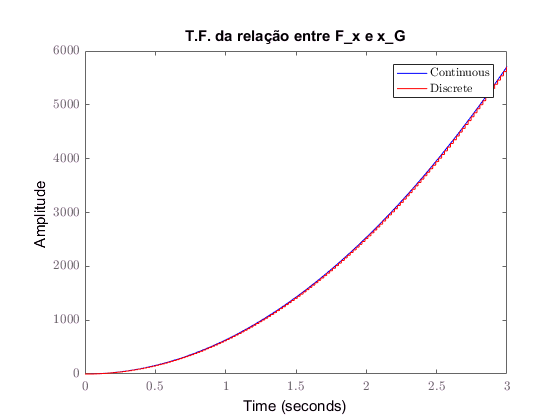

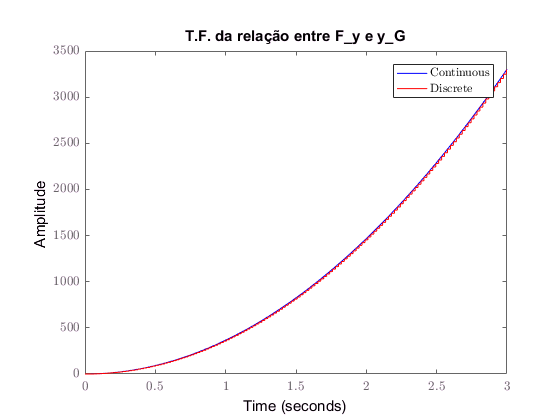

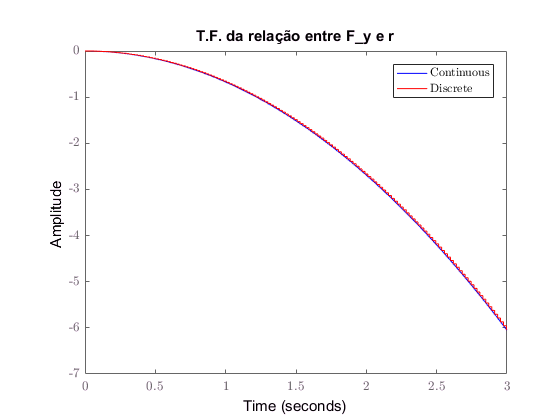

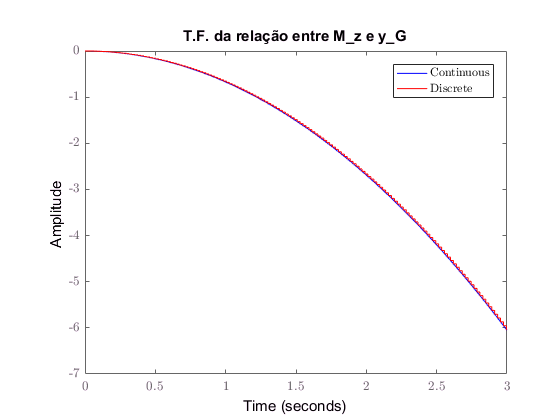

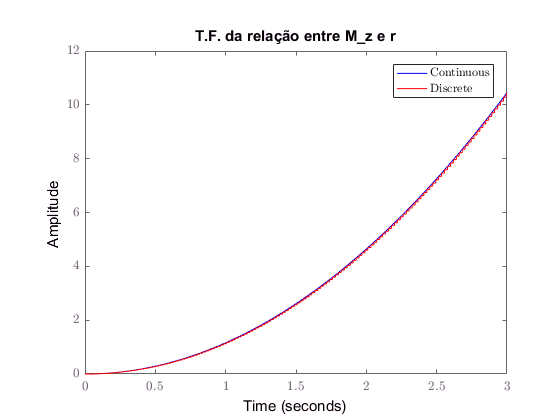

sys=ss(A,B,C,0);
sys_d=c2d(sys,T_a);

x=[1 2 2 3 3];
y=[1 2 3 2 3];

t_step=3;

title_list={'T.F. da relação entre F_x e x_G'... 
            'T.F. da relação entre F_y e y_G'...
            'T.F. da relação entre F_y e r'...
            'T.F. da relação entre M_z e y_G'...
            'T.F. da relação entre M_z e r'};
for i=1:5
    figure;
    step(sys(y(i),x(i)),t_step,'b')
    hold on
    step(sys_d(y(i),x(i)),t_step,'r')
    title(title_list(i),'Interpreter','latex')
    legend('Continuous','Discrete')
end

Pela análise dos gráficos, pode-se perceber que o período de amostragem adotado tem desempenho muito satisfatório